## Exercício 6

**(a)**

T = [0.8 0 0 0.3 0
    0.2 0.6 0 0.2 0
    0 0.3 1 0 0
    0 0.1 0 0.4 0
    0 0 0 0.1 1]

T =     0.8000         0         0    0.3000         0
    0.2000    0.6000         0    0.2000         0
         0    0.3000    1.0000         0         0
         0    0.1000         0    0.4000         0
         0         0         0    0.1000    1.0000


**(b)**

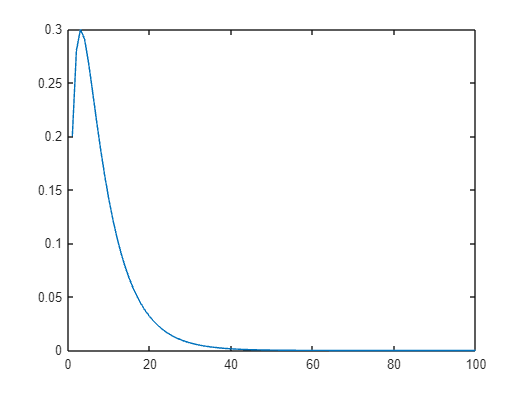

x = [1 0 0 0 0]';
probs3 = zeros(1,100);

for i = 1:100
    p = T^i*x;
    probs3(i) = p(2);
end

plot(probs3);

**(c)**

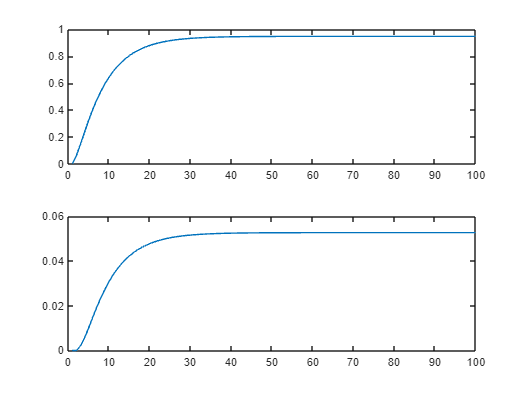

probs3 = zeros(1,100);
probs5 = zeros(1,100);

for i = 1:100
    p = T^i*x;
    probs3(i) = p(3);
    probs5(i) = p(5);
end

subplot(211)
plot(probs3)
subplot(212)
plot(probs5)

**(d)**

% forma canonica
aux = [0.8 0   0.3 0 0
     0.2 0.6 0.2 0 0
     0   0.1 0.4 0 0
     0   0.3 0   1 0
     0   0   0.1 0 1];
% 2 estados absorventes criam entao uma matriz 2x2 no seu cantinho. é
% preciso trocar ordens de vez em quando, o 0.3 troca com o 0.1 na coluna
% 2, o 0.4 com o 0 na coluna 3 e o 1 com o 0.
Q = aux(1:3, 1:3)

Q =     0.8000         0    0.3000
    0.2000    0.6000    0.2000
         0    0.1000    0.4000


**(e)**

% F = (I - Q)^-1
F = (eye(3) - Q)^-1

F =     5.7895    0.7895    3.1579
    3.1579    3.1579    2.6316
    0.5263    0.5263    2.1053


**(f)**

x1 = [1 0 0]';
x2 = [0 1 0]';
x4 = [0 0 1]';

sum(F*x1)

ans = 9.4737

sum(F*x2)

ans = 4.4737

sum(F*x4)

ans = 7.8947

**(g)**

R = aux(4:5, 1:3);
B = R*F;

B(1,1)

ans = 0.9474

B(2,1)

ans = 0.0526